## Setup the Import Options

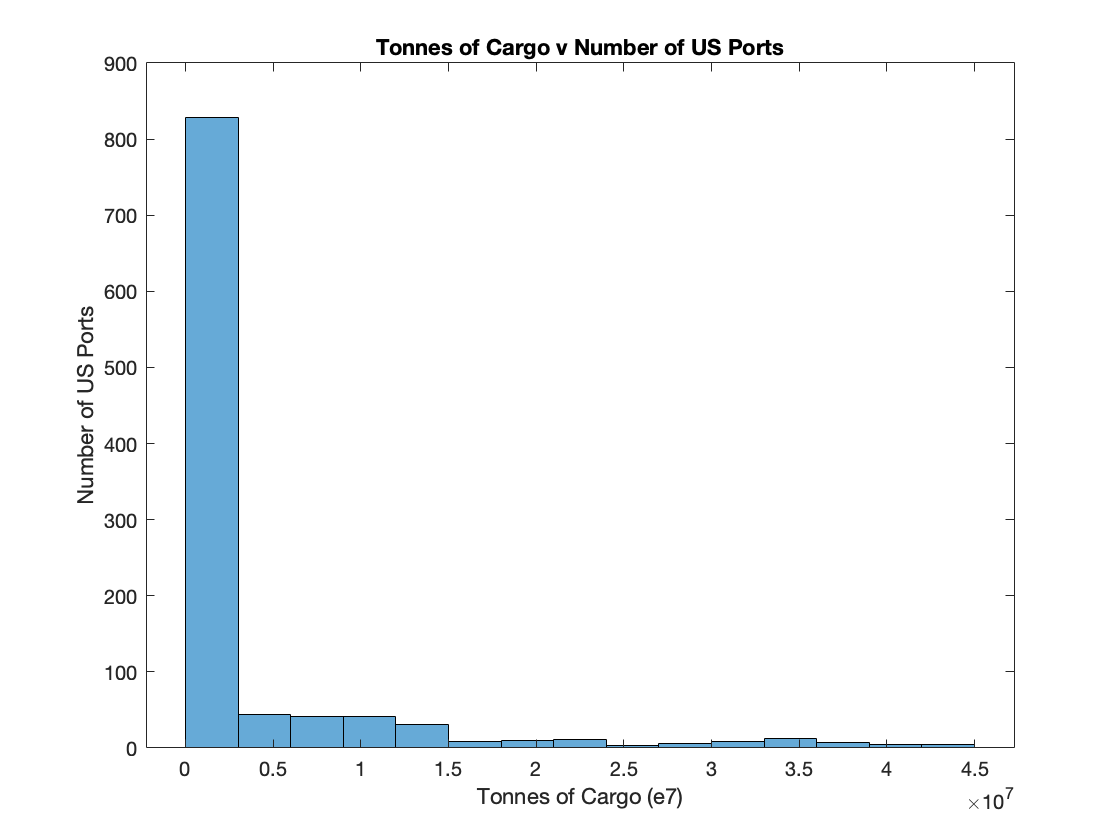

opts = spreadsheetImportOptions("NumVariables", 20);
% Specify sheet and range
opts.Sheet = "Total Metric Tons (MT)";
opts.DataRange = "A6:T66";

% Specify column names and types
opts.VariableNames = ["USCustomPorts", "Coast", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];
opts = setvaropts(opts, [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20], "WhitespaceRule", "preserve");
opts = setvaropts(opts, [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20], "EmptyFieldRule", "auto");

% Import the data
data = readtable("/Users/nickbanull/Documents/GitHub/Final-Project/container-ports-2000-2017.xlsx", opts, "UseExcel", false);
data = table2array(data);

%extracting numeric values
dataex = str2double(data);

%histogram
histogram(dataex)
title('Tonnes of Cargo v Number of US Ports')
xlabel('Tonnes of Cargo (e7)')
ylabel('Number of US Ports')


%Variance
variance = var(dataex(57,[3:end]))

variance = 3.1345e+10


%standarddeviation
deviation = sqrt(variance)

deviation = 1.7704e+05

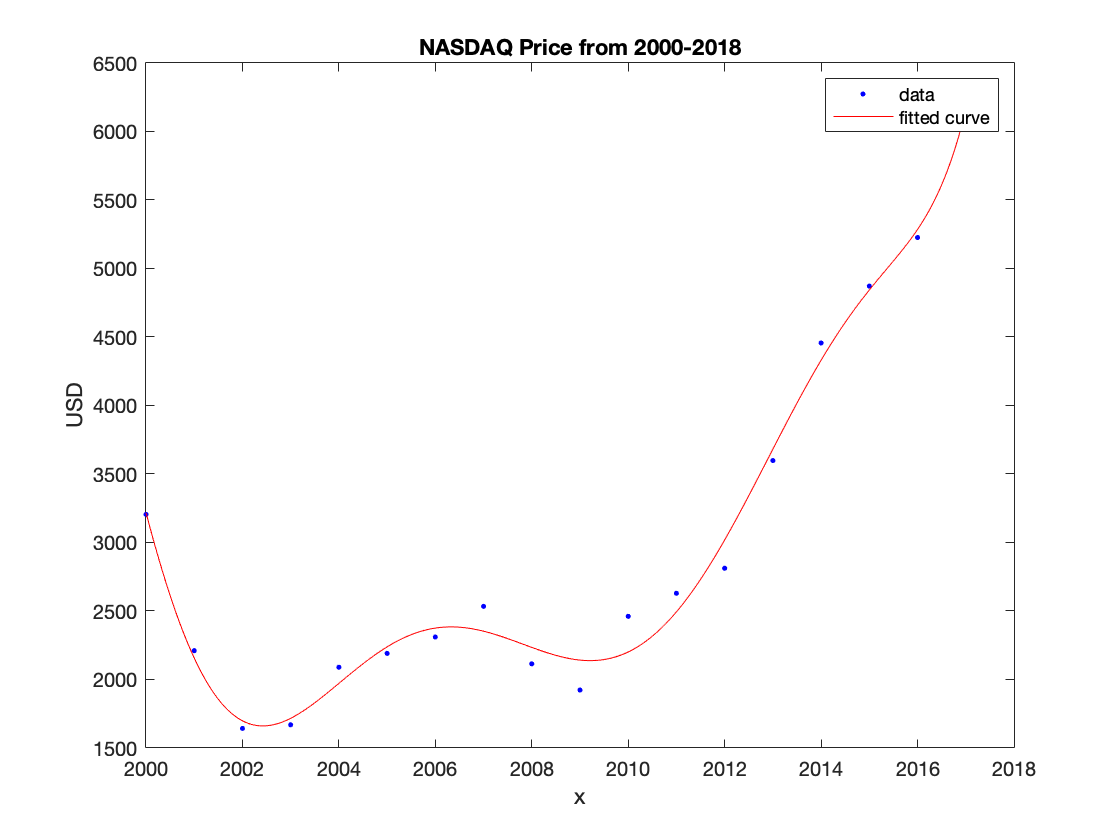


%importingstockdata

opts1 = spreadsheetImportOptions("NumVariables", 2);
opts1.Sheet = "Sheet1";
opts1.DataRange = "A2:B217";
opts1.VariableNames = ["Date", "Close"];
opts1.VariableTypes = ["datetime", "double"];
sdata = readtable("/Users/nickbanull/Documents/GitHub/Final-Project/NASDAQ.xlsx", opts1, "UseExcel", false);
values = sdata(:,2);
avalues = table2array(values);
    avg2000 = mean(avalues([1,12],1));
    avg2001 = mean(avalues([12,24],1));
    avg2002 = mean(avalues([24,36],1));
    avg2003 = mean(avalues([36,48],1));
    avg2004 = mean(avalues([48,60],1));
    avg2005 = mean(avalues([60,72],1));
    avg2006 = mean(avalues([72,84],1));
    avg2007 = mean(avalues([84,96],1));
    avg2008 = mean(avalues([96,108],1));
    avg2009 = mean(avalues([108,120],1));
    avg2010 = mean(avalues([120,132],1));
    avg2011 = mean(avalues([132,144],1));
    avg2012 = mean(avalues([144,156],1));
    avg2013 = mean(avalues([156,168],1));
    avg2014 = mean(avalues([168,180],1));
    avg2015 = mean(avalues([180,192],1));
    avg2016 = mean(avalues([192,204],1));
    avg2017 = mean(avalues([204,216],1));
stockyval = [avg2000,avg2001,avg2002,avg2003,avg2004,avg2005,avg2006,avg2007,avg2008,avg2009,avg2010,avg2011,avg2012,avg2013,avg2014,avg2015,avg2016,avg2017];
stockyval = stockyval.';
stockxval = linspace(2000,2017,18);
stockxval = stockxval.';
f1 = fit(stockxval,stockyval,'fourier4');
plot(f1,stockxval,stockyval)

title('NASDAQ Price from 2000-2018')
ylabel('USD')

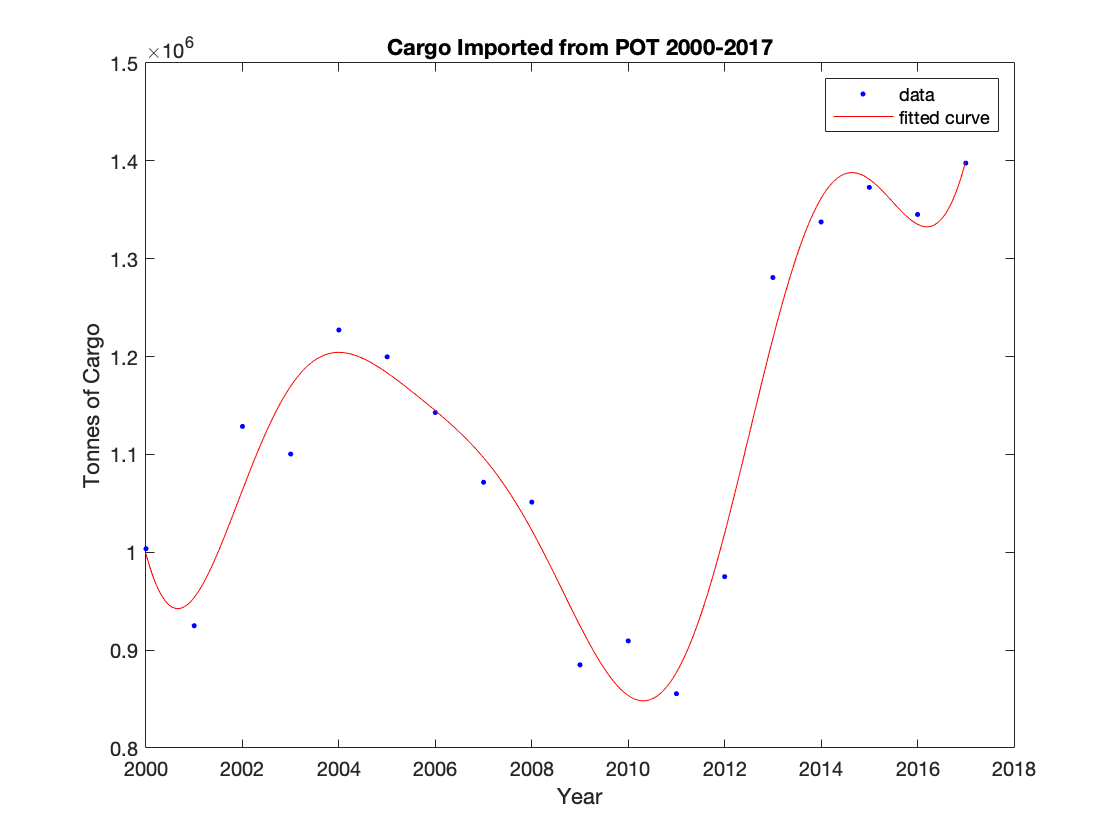


%scatterplot
y1 = dataex(57,[3:end]);
x1 = [2000:2017];
x1 = x1.';
y1 = y1.';
f=fit(x1,y1,'fourier4');
plot(f,x1,y1)
title('Cargo Imported from POT 2000-2017')
xlabel('Year')
ylabel('Tonnes of Cargo')


%coorelation between NASDAQ Price and Cargo

A = [stockyval, y1];
R = corrcoef(A)

R =     1.0000    0.7045
    0.7045    1.0000


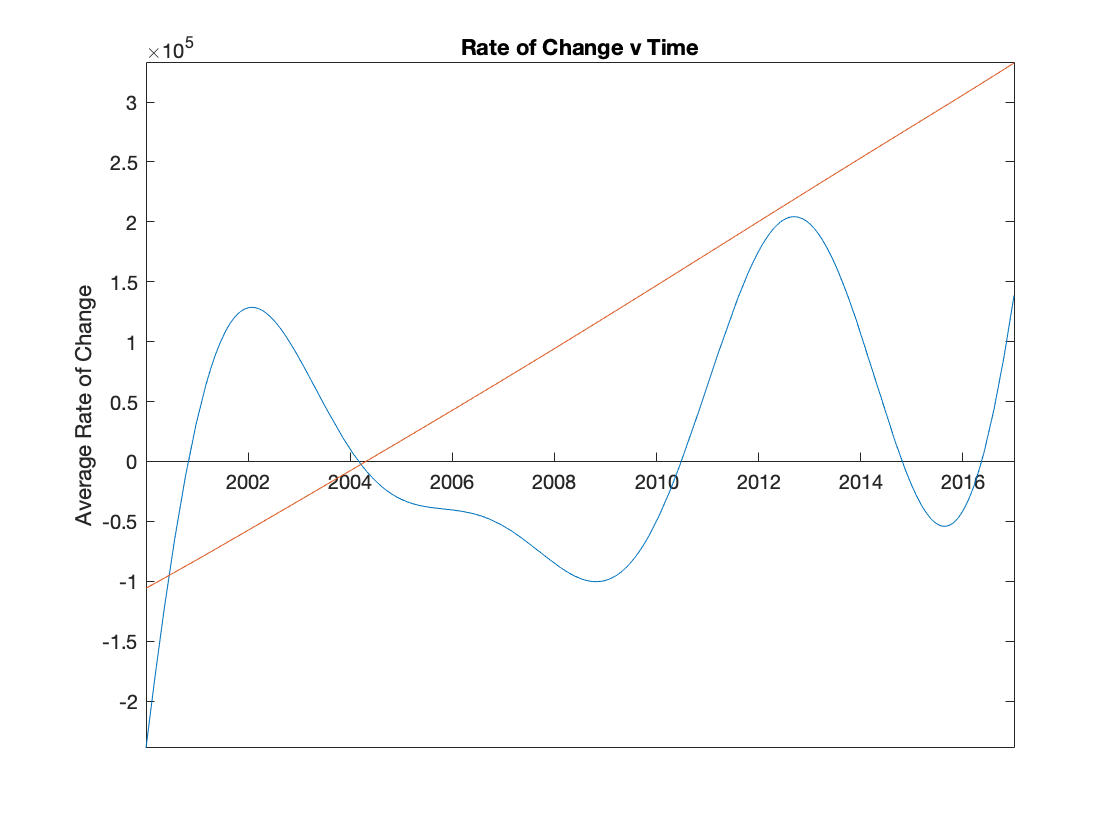


%Analysis of Line of Best Fit
syms x
       a0 =   1.683e+06;
       a1 =  -4.689e+05;
       b1 =   9.684e+05;
       a2 =  -4.138e+05;
       b2 =   -5.34e+05;
       a3 =   4.729e+05;
       b3 =   1.035e+05;
       a4 =  -9.162e+04;
       b4 =   1.598e+05;
       w =      0.2341;
       a5 =   1.353e+11; 
       a6 =    6.46e+10; 
       b5 =  -2.278e+11;
       a7 =  -1.144e+11;
       b6 =  -8.868e+10; 
       a8 =  -4.716e+10;
       b7 =   2.118e+10; 
       a9 =   -1.08e+09; 
       b8 =   7.889e+09; 
       w1 = 0.01677;
f = @(x) a0 + a1*cos(x*w) + b1*sin(x*w) + a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + a4*cos(4*x*w) + b4*sin(4*x*w);
    dfport = diff(f,x);
f1 = @(x) a5 + a6*cos(x*w1) + b5*sin(x*w1) + a7*cos(2*x*w1) + b6*sin(2*x*w1) + a8*cos(3*x*w1) + b7*sin(3*x*w1) + a9*cos(4*x*w1) + b8*sin(4*x*w1);
     dfnas = diff(f1,x);

%Graphing Derivatives
     
fplot(dfport, [2000,2017]);
hold on
fplot(dfnas, [2000, 2017]);
title('Rate of Change v Time')
ylabel('Average Rate of Change')
ax = gca;
ax.XAxisLocation = 'origin';